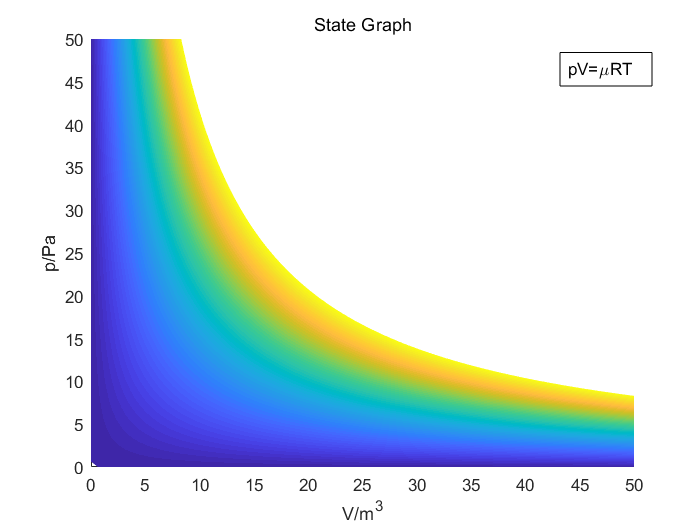

clear;
fig = figure;
ax = gca;

range = [0,50,0,50,0,50];
hold(ax,'on');
title('State Graph');
xlabel('V/m^3');
ylabel('p/Pa');
zlabel('T/K');
axis(ax,range);

fimplicit3(@(V,p,T)(p.*V-8.31*T),range,'meshdensity',80,'edgecolor','none');
an = annotation('textbox',[0.8,0.8,0.1,0.1],'String','pV=\muRT','fitboxtotext','on');